# PART B: ADAPTIVE EQUALIZATION

## setup

N = 1000;
V = [-1, 1];
train = V(randi([1,2], 1, N));
window = 50;

## helper functions

function [gn, en, yn, xn, noi_power] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N, init)
    % channel convolution
    chan_output = conv(h, train);
    chan_output = chan_output(1:N);

    % adding noise
    sig_power = mean(chan_output.^2);
    noi_power = sig_power / 10^(snr_db/10);
    xn        = chan_output + sqrt(noi_power) .* randn(1, N);

    delayed_train = [zeros(1, delay_idx), train(1:end-delay_idx)];

    if nargin < 8 || strcmp(init, 'zeros')
        gn = zeros(1, M+1);         % default: all zeros
    elseif strcmp(init, 'random')
        gn = 0.01 * randn(1, M+1); % small random values
    elseif strcmp(init, 'impulse')
        gn = [1, zeros(1, M)];      % identity start
    end

    yn = zeros(1, N);
    en = zeros(1, N);

    for i = M+1:N
        x_inp = xn(i:-1:i-M);
        yn(i) = dot(gn, x_inp);
        en(i) = delayed_train(i) - yn(i);
        gn    = gn + 2*mu * en(i) * x_inp;
    end
end

function plot_channel(h, snr_db, mu, M)
    figure('Position', [100, 100, 700, 900]);   % [x, y, width, height]
    sgtitle({compose("Channel Plots: h=%s", mat2str(h)), ...
         compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});
    subplot(3,1,1);
    stem(h);
    xlabel('n'); ylabel('h[n]');
    title('Channel Impulse Response');
    grid on;

    subplot(3,1,2);
    [H_chan, w] = freqz(h, 1, 1024);
    plot(w/pi, 20*log10(abs(H_chan)));
    xlabel('\omega/\pi'); ylabel('|H| (dB)');
    title('Channel Frequency Response');
    grid on;

    subplot(3,1,3);
    zplane(h, 1);
    title('Channel Pole-Zero Plot');
end

function plot_equalizer(h, gn, en, snr_db, mu, M, window)
    figure('Position', [100, 100, 700, 1100]);  % taller for extra subplot
    sgtitle({"Equalizer Plots: h=" + mat2str(h), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});

    subplot(4,1,1);
    stem(gn);
    xlabel('n'); ylabel('g[n]');
    title(sprintf('Equalizer Impulse Response (M=%d)', M));
    grid on;

    [G, w] = freqz(gn, 1, 1024);

    subplot(4,1,2);
    plot(w/pi, 20*log10(abs(G)));
    xlabel('\omega/\pi'); ylabel('|G| (dB)');
    title('Equalizer Frequency Response (dB)');
    grid on;

    subplot(4,1,3);
    plot(w/pi, abs(G));
    xlabel('\omega/\pi'); ylabel('|G|');
    title('Equalizer Frequency Response (linear)');
    grid on;

    subplot(4,1,4);
    mse = conv(en(M+1:end).^2, ones(1,window)/window, 'same');
    plot(10*log10(mse));
    xlabel('Iteration n'); ylabel('MSE (dB)');
    title(sprintf('Learning Curve (M=%d, \\mu=%.4f, SNR=%ddB)', M, mu, snr_db));
    grid on;
end

function plot_cascade(h, gn, snr_db, mu, M)
    figure('Position', [100, 100, 700, 1000]);
    sgtitle({"Cascade (h*g) Plots: h=" + mat2str(h), ...
             compose("M=%d, μ=%.5f, SNR=%.1fdB", M, mu, snr_db)});
    cascade_h = conv(h, gn);
    [H_cas, w] = freqz(cascade_h, 1, 1024);

    subplot(3,1,1);
    stem(cascade_h);
    xlabel('n'); ylabel('Amplitude');
    title('Cascade (h * g) Impulse Response');
    grid on;

    subplot(3,1,2);
    plot(w/pi, 20*log10(abs(H_cas)));
    hold on;
    yline(0, 'r--', 'LineWidth', 1.0);
    hold off;
    xlabel('\omega/\pi'); ylabel('Magnitude (dB)');
    title('Cascade Frequency Response (dB)');
    grid on;

    subplot(3,1,3);
    plot(w/pi, abs(H_cas));
    hold on;
    yline(1, 'r--', 'LineWidth', 1.0);  % reference line at 1
    hold off;
    xlabel('\omega/\pi'); ylabel('|H_{cas}|');
    title('Cascade Frequency Response (linear, ideal = 1)');
    grid on;
end

function [ber_uneq, ber_eq] = compute_bit_error(h, gn, M, delay_idx, noi_power, V)
    N_test  = 5000;
    s_test  = V(randi([1,2], 1, N_test));
    x_test  = conv(s_test, h);
    x_test  = x_test(1:N_test);
    x_test  = x_test + sqrt(noi_power)*randn(1, N_test);

    s_test_del = [zeros(1,delay_idx), s_test(1:N_test-delay_idx)];

    % unequalized
    dec_uneq = sign([zeros(1,delay_idx), x_test(1:N_test-delay_idx)]);
    ber_uneq = sum(dec_uneq ~= s_test_del) / N_test;

    % equalized
    y_test = zeros(1, N_test);
    for k = M+1:N_test
        x_vec     = x_test(k:-1:k-M);
        y_test(k) = dot(gn, x_vec);
    end
    dec_eq  = sign(y_test(M+1:end));
    ber_eq  = sum(dec_eq ~= s_test_del(M+1:end)) / (N_test-M);
end

## TESTS

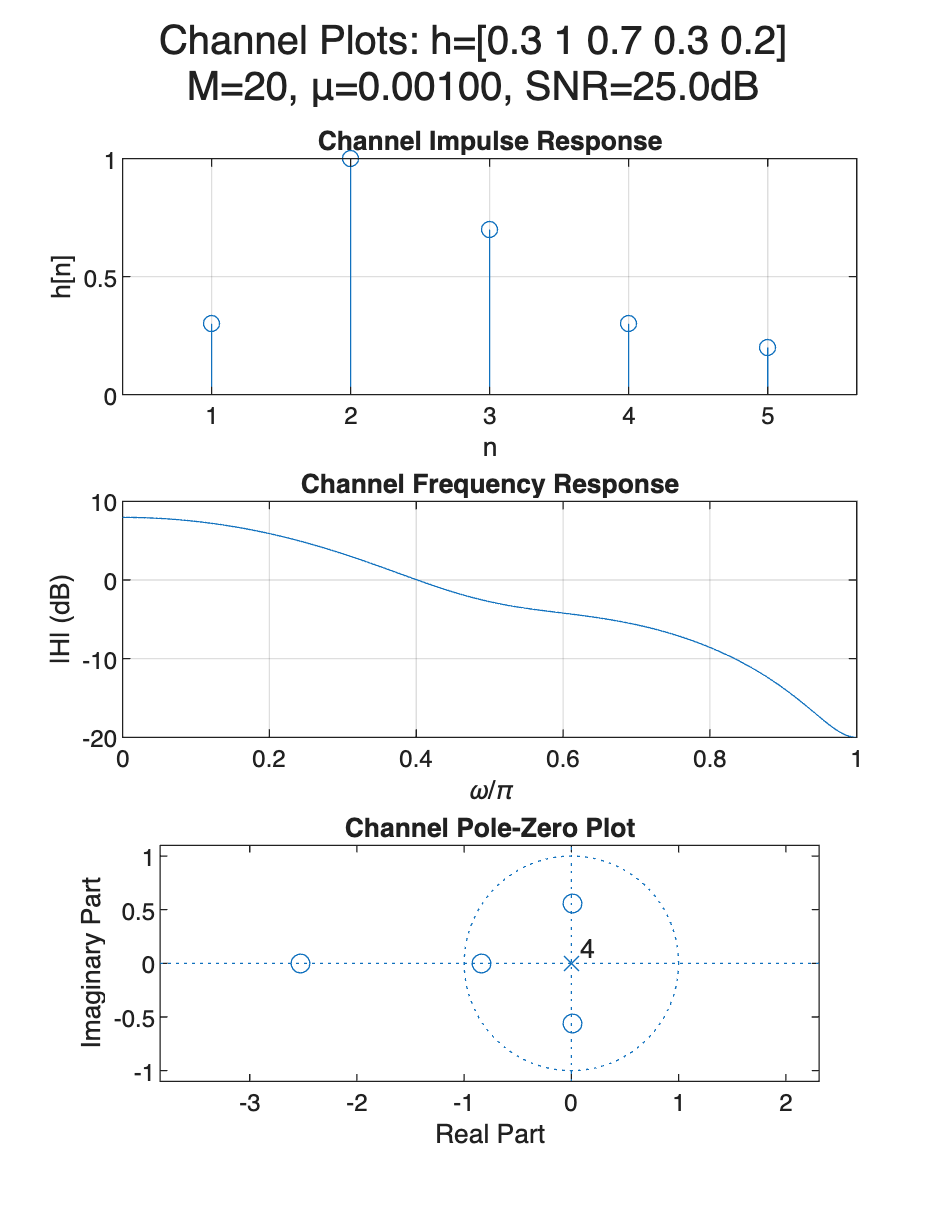

% TEST 1 (basic config)
snr_db = 25;
h = [0.3, 1, 0.7, 0.3, 0.2];
mu = 0.001;
M = 20;
delay_idx = 2;

[gn, en, yn, xn, noi_power] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N);

figure; plot_channel(h, snr_db, mu, M);

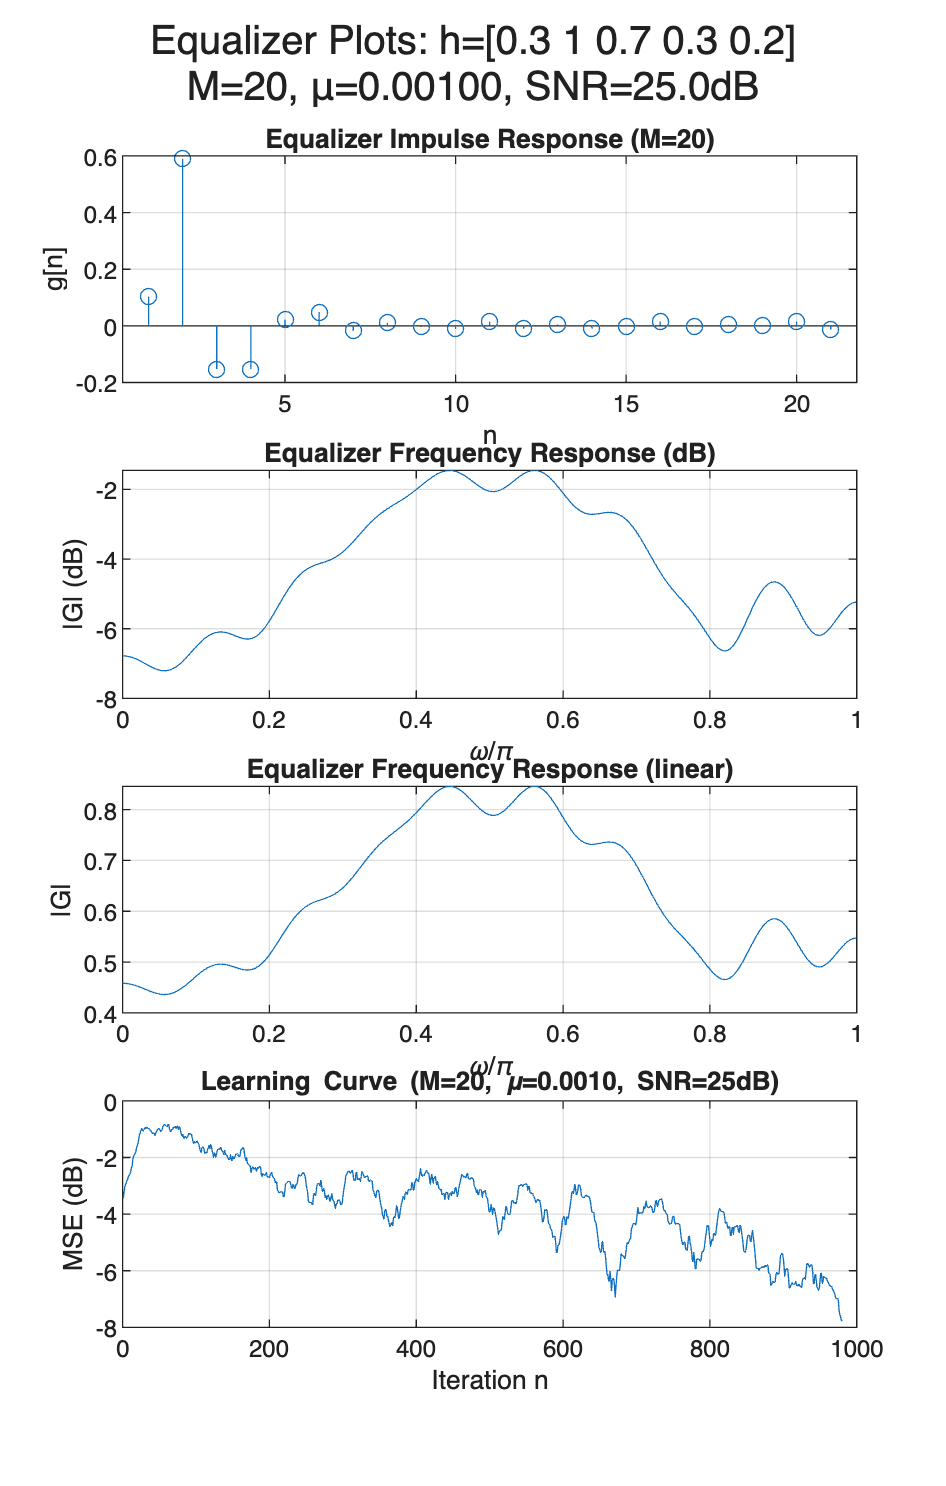

figure; plot_equalizer(h, gn, en, snr_db, mu, M, window);

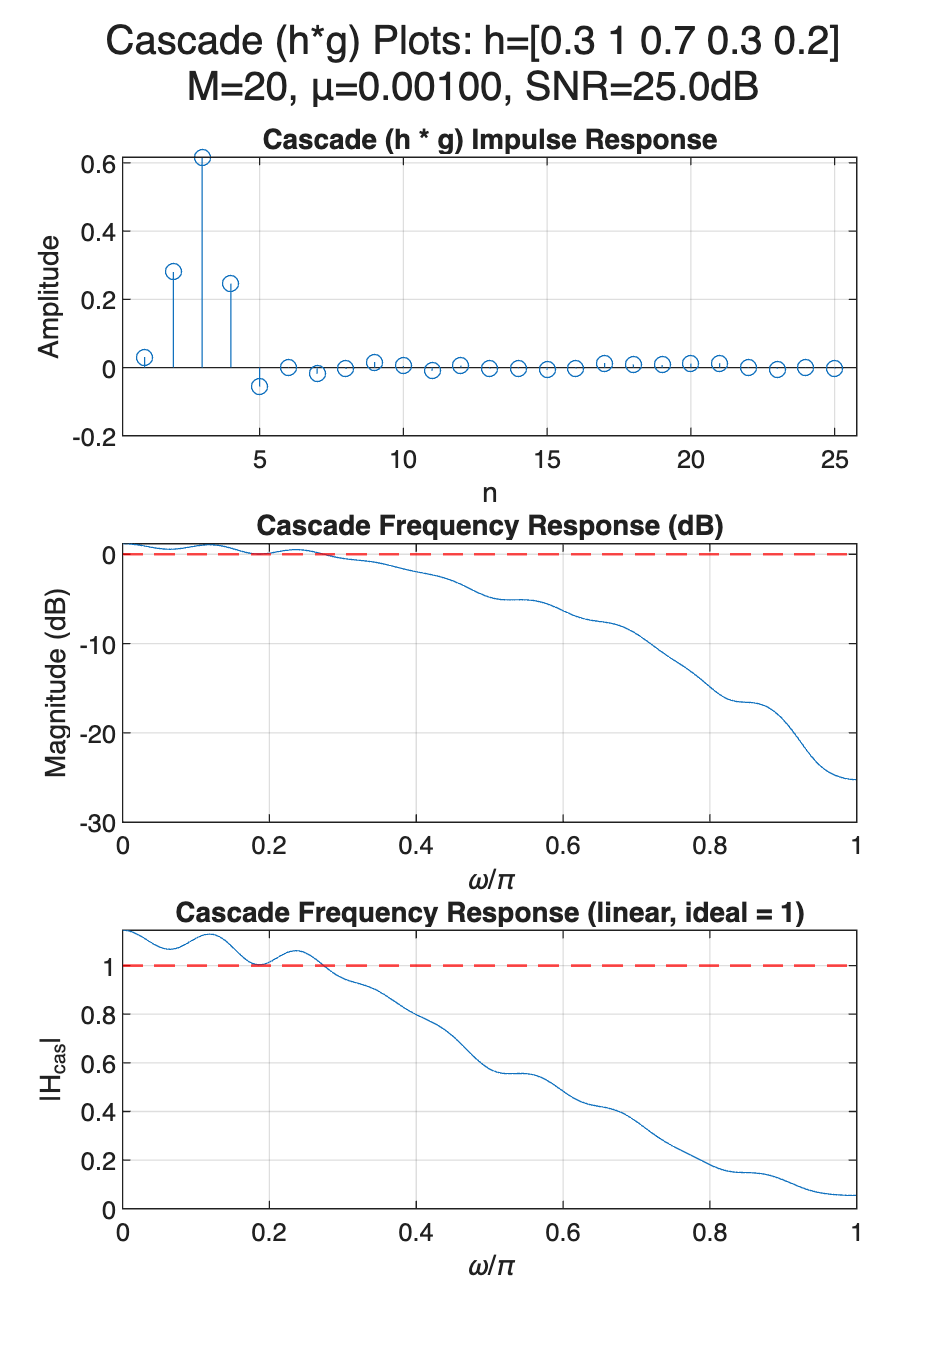

figure; plot_cascade(h, gn, snr_db, mu, M);


[BER_uneq, BER_eq] = compute_bit_error(h, gn, M, delay_idx, noi_power, V);
fprintf('Test 1 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);

Test 1 (SNR=25dB, M=20, mu=0.0010)


fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.3868


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.0404


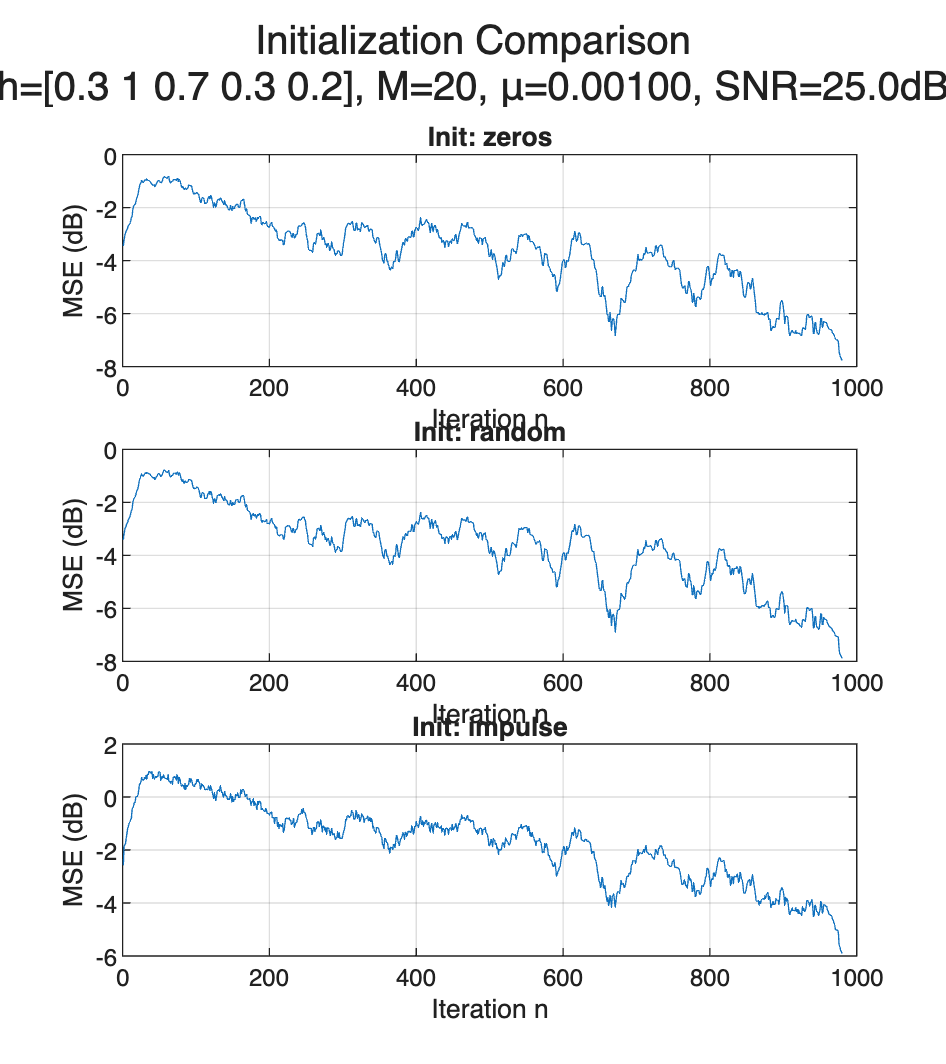


% check initialization comparison
inits = {'zeros', 'random', 'impulse'};

figure('Position', [100, 100, 800, 900]);
sgtitle({'Initialization Comparison', ...
         compose("h=%s, M=%d, μ=%.5f, SNR=%.1fdB", mat2str(h), M, mu, snr_db)});

for k = 1:length(inits)
    [gn_init, en_init, ~, ~, ~] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N, inits{k});
    
    mse_init = conv(en_init(M+1:end).^2, ones(1,window)/window, 'same');
    
    subplot(3,1,k);
    plot(10*log10(mse_init));
    xlabel('Iteration n'); ylabel('MSE (dB)');
    title(sprintf('Init: %s', inits{k}));
    grid on;
end

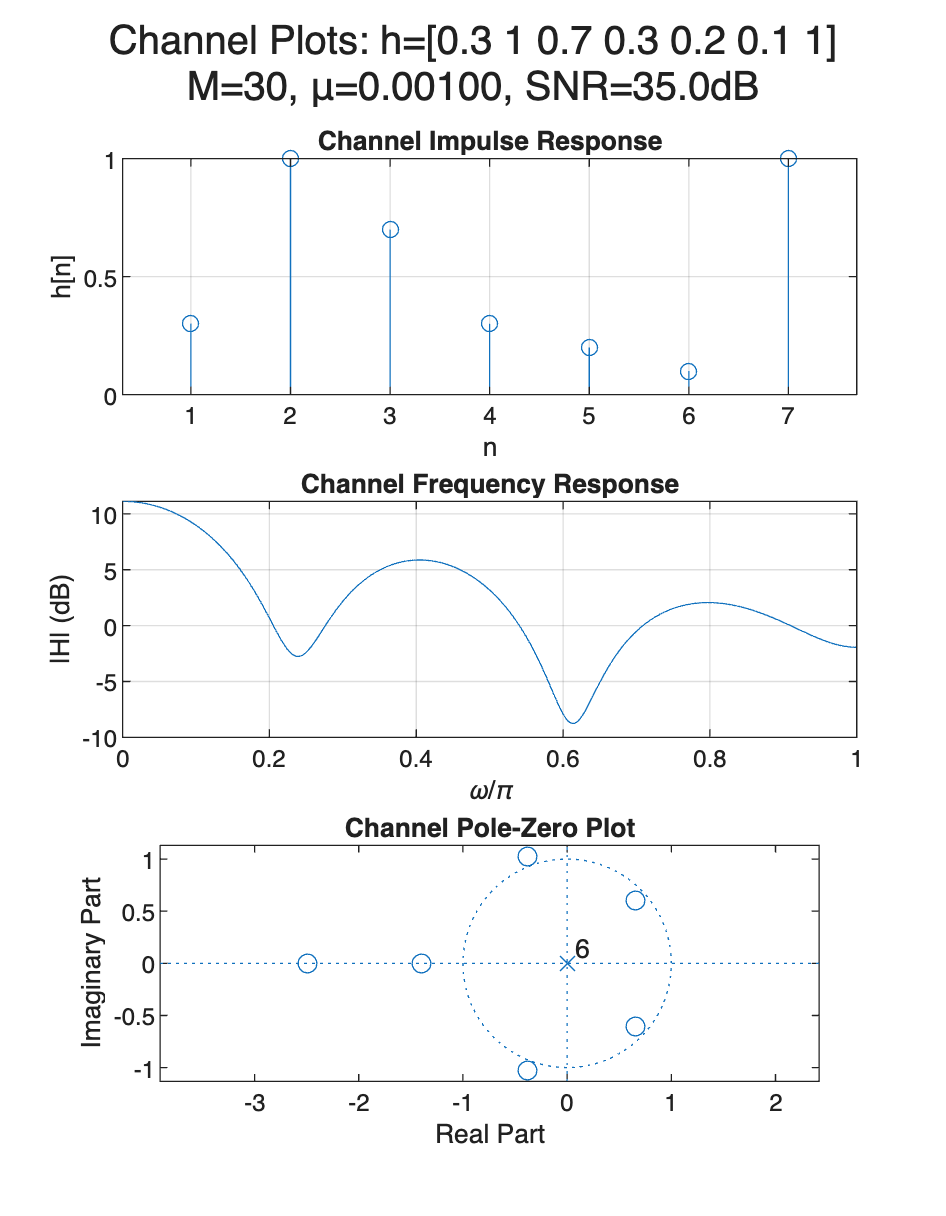

% TEST 2 (higher snr, longer h, same mu, higher M, more delay)
snr_db = 35;
h = [0.3, 1, 0.7, 0.3, 0.2, 0.1, 1];
mu = 0.001;
M = 30;
delay_idx = 3;

[gn, en, yn, xn, noi_power] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N);

figure; plot_channel(h, snr_db, mu, M);

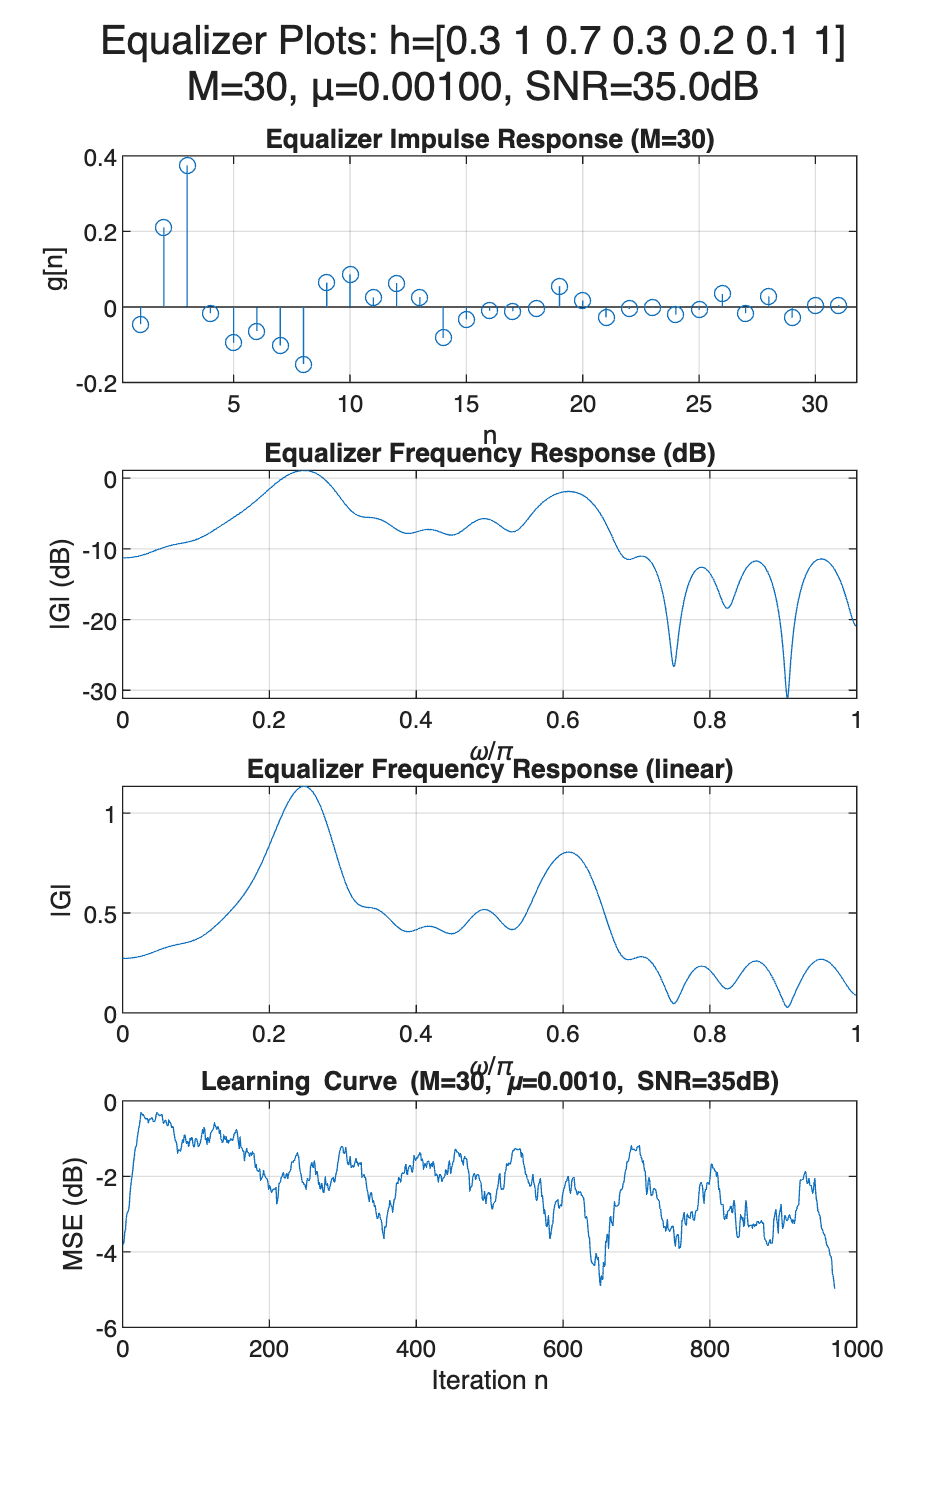

figure; plot_equalizer(h, gn, en, snr_db, mu, M, window);

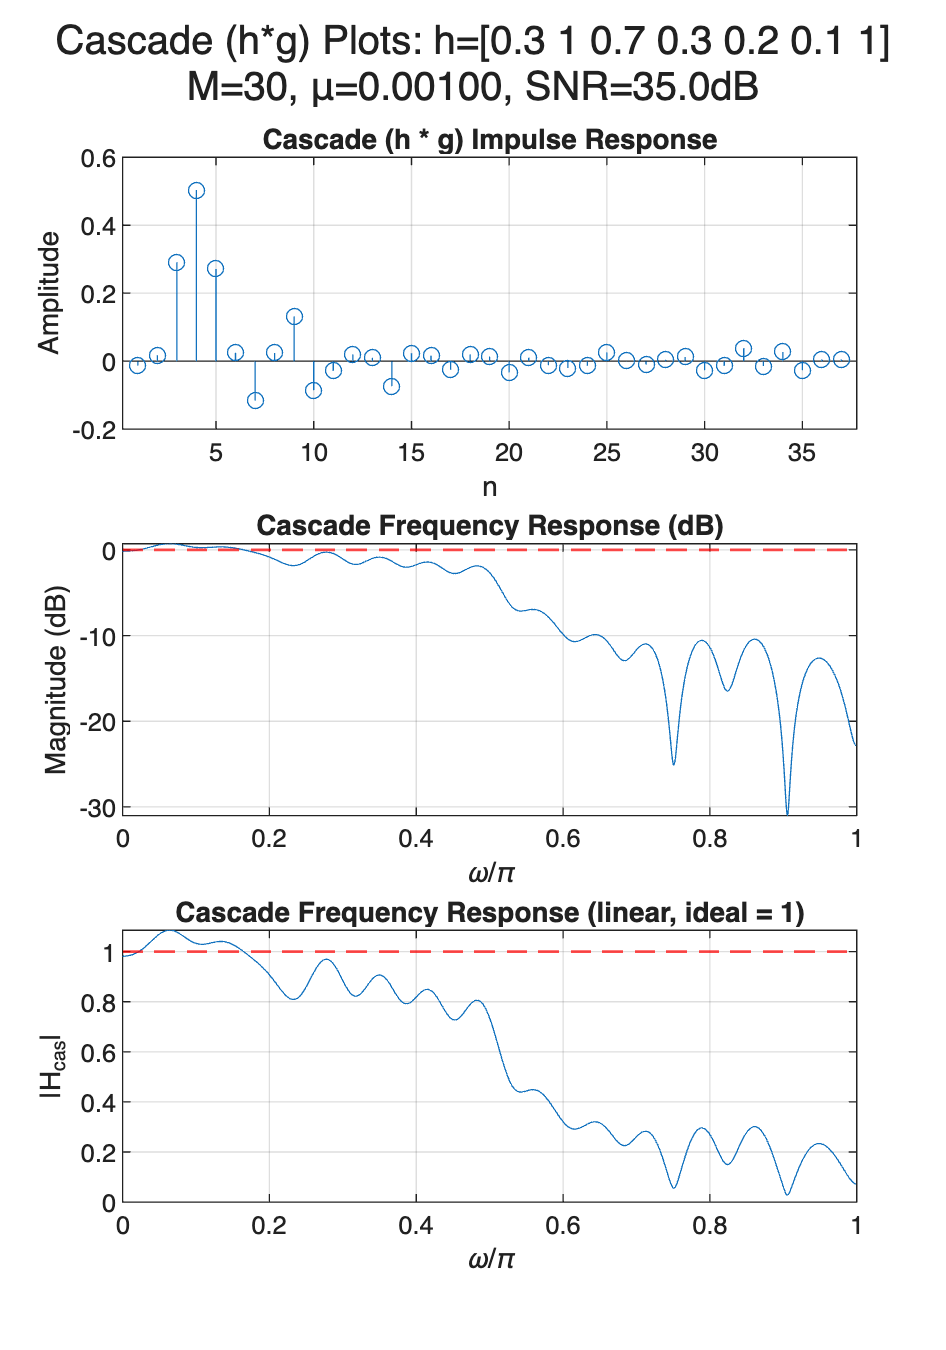

figure; plot_cascade(h, gn, snr_db, mu, M);


[BER_uneq, BER_eq] = compute_bit_error(h, gn, M, delay_idx, noi_power, V);
fprintf('Test 2 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);

Test 2 (SNR=35dB, M=30, mu=0.0010)


fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.4554


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.1634


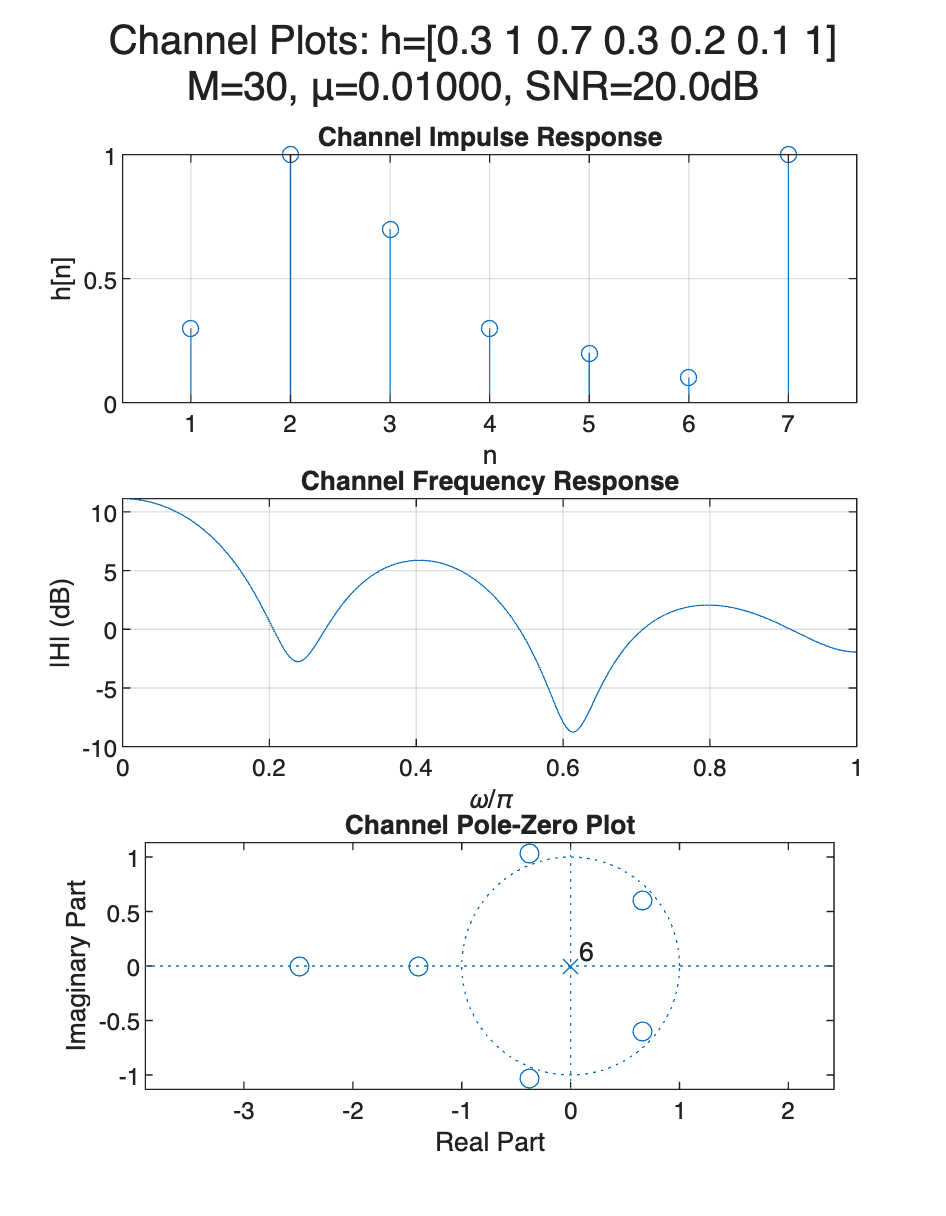

% TEST 3 (lower snr, same h, higher mu, same M, same delay)
snr_db = 20;
h = [0.3, 1, 0.7, 0.3, 0.2, 0.1, 1];
mu = 0.01;
M = 30;
delay_idx = 3;

[gn, en, yn, xn, noi_power] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N);

figure; plot_channel(h, snr_db, mu, M);

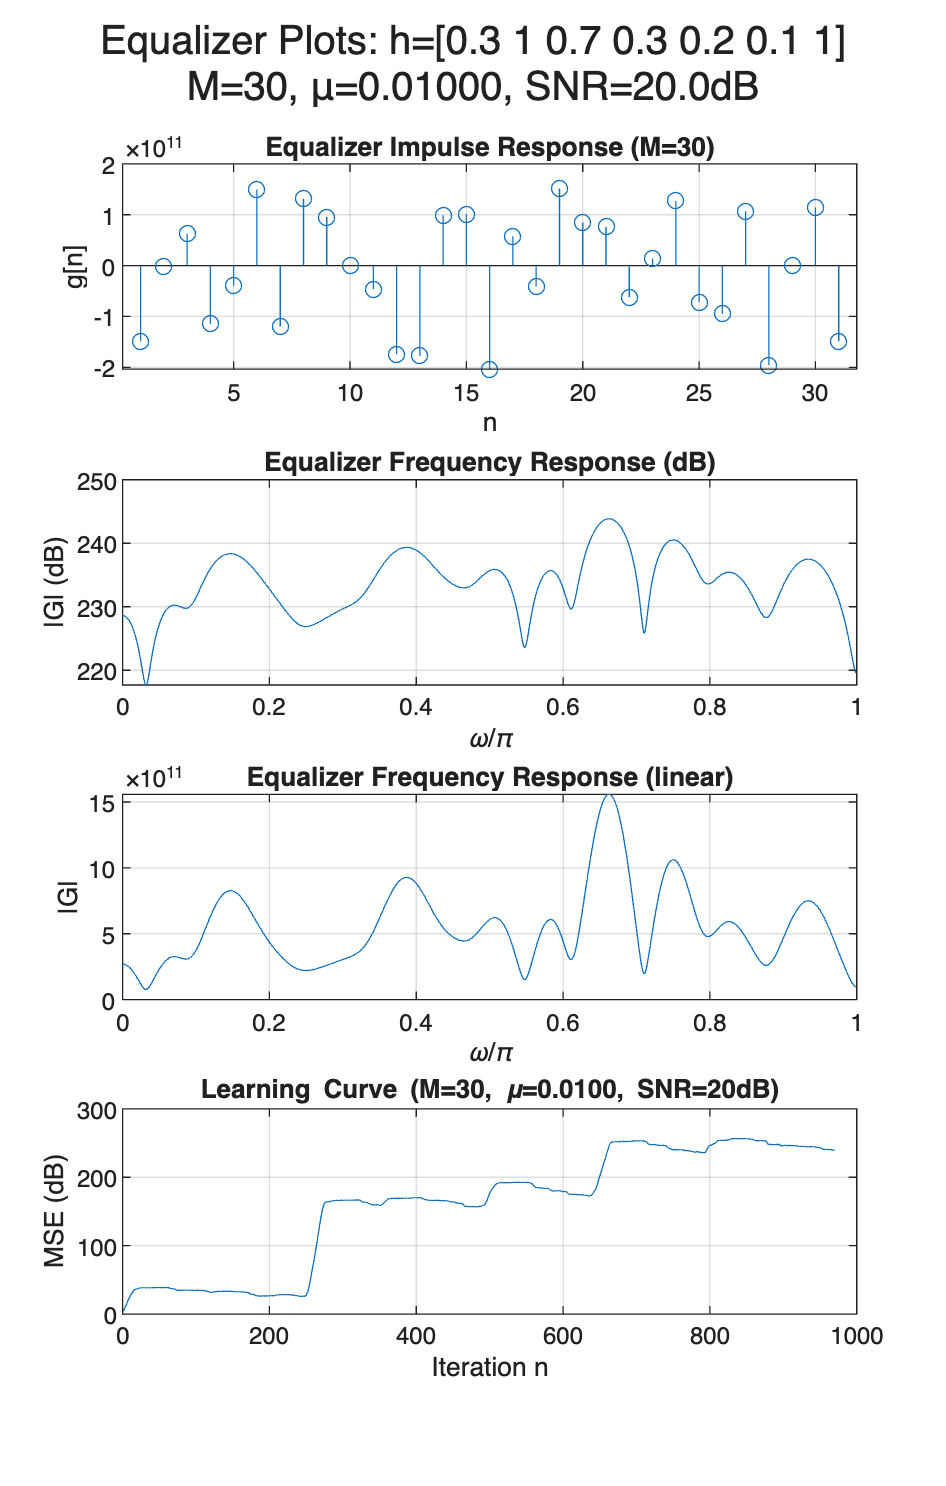

figure; plot_equalizer(h, gn, en, snr_db, mu, M, window);

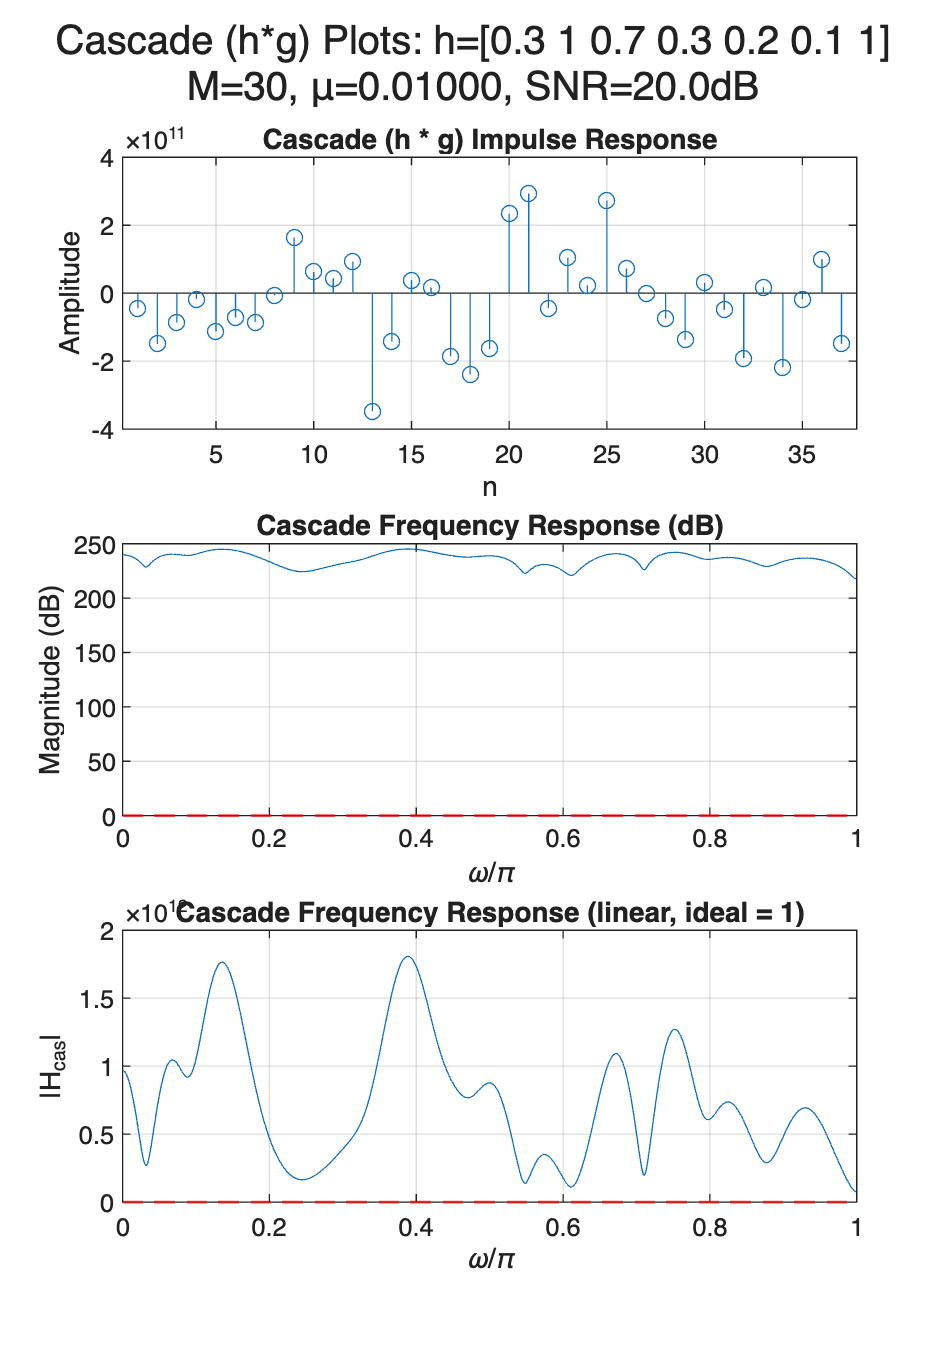

figure; plot_cascade(h, gn, snr_db, mu, M);


[BER_uneq, BER_eq] = compute_bit_error(h, gn, M, delay_idx, noi_power, V);
fprintf('Test 3 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);

Test 3 (SNR=20dB, M=30, mu=0.0100)


fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.4518


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.5129


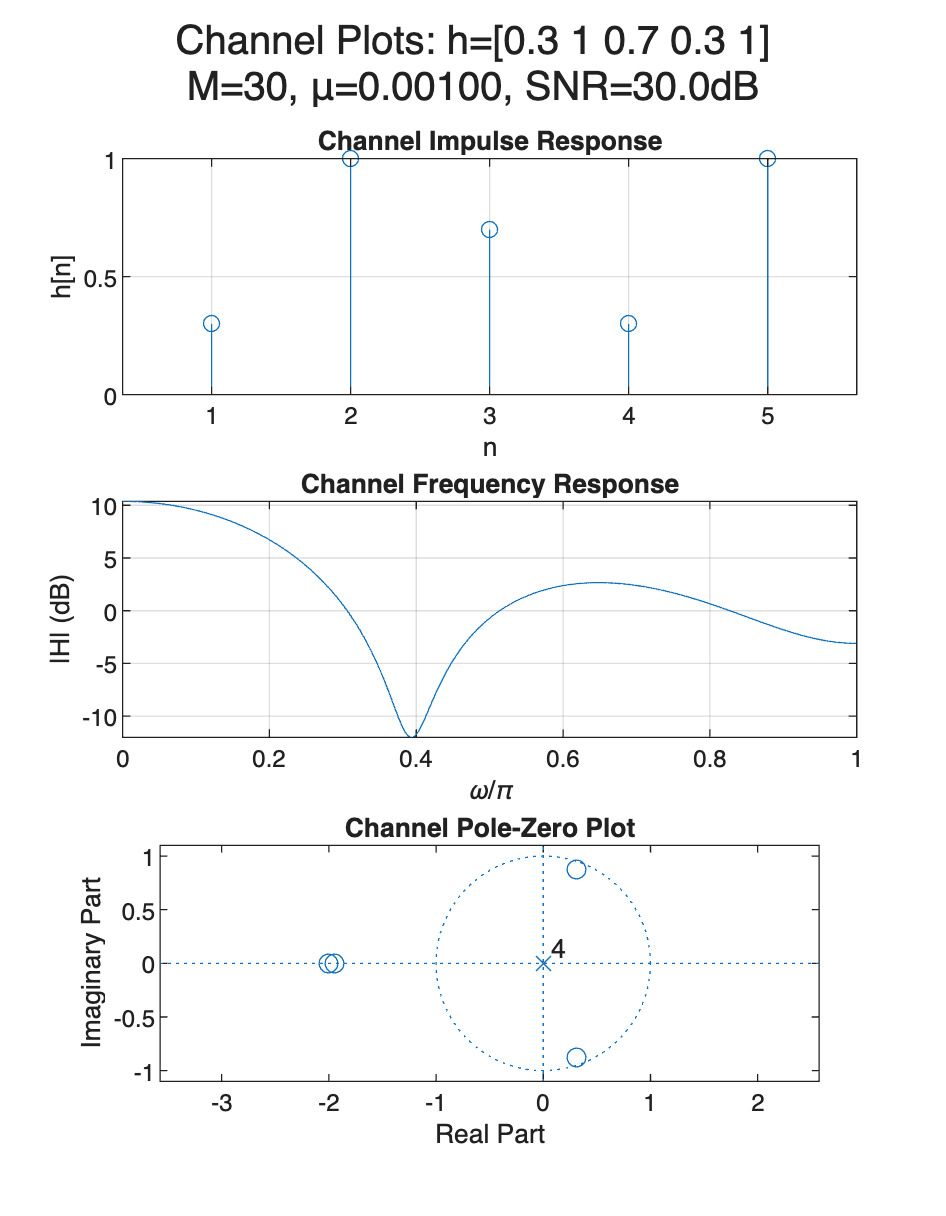

% TEST 4 (30 snr, shorter h, smaller mu, 30 M, 2 delay)
snr_db = 30;
h = [0.3, 1, 0.7, 0.3, 1];
mu = 0.001;
M = 30;
delay_idx = 3;

[gn, en, yn, xn, noi_power] = run_equalizer(train, h, mu, M, delay_idx, snr_db, N);

figure; plot_channel(h, snr_db, mu, M);

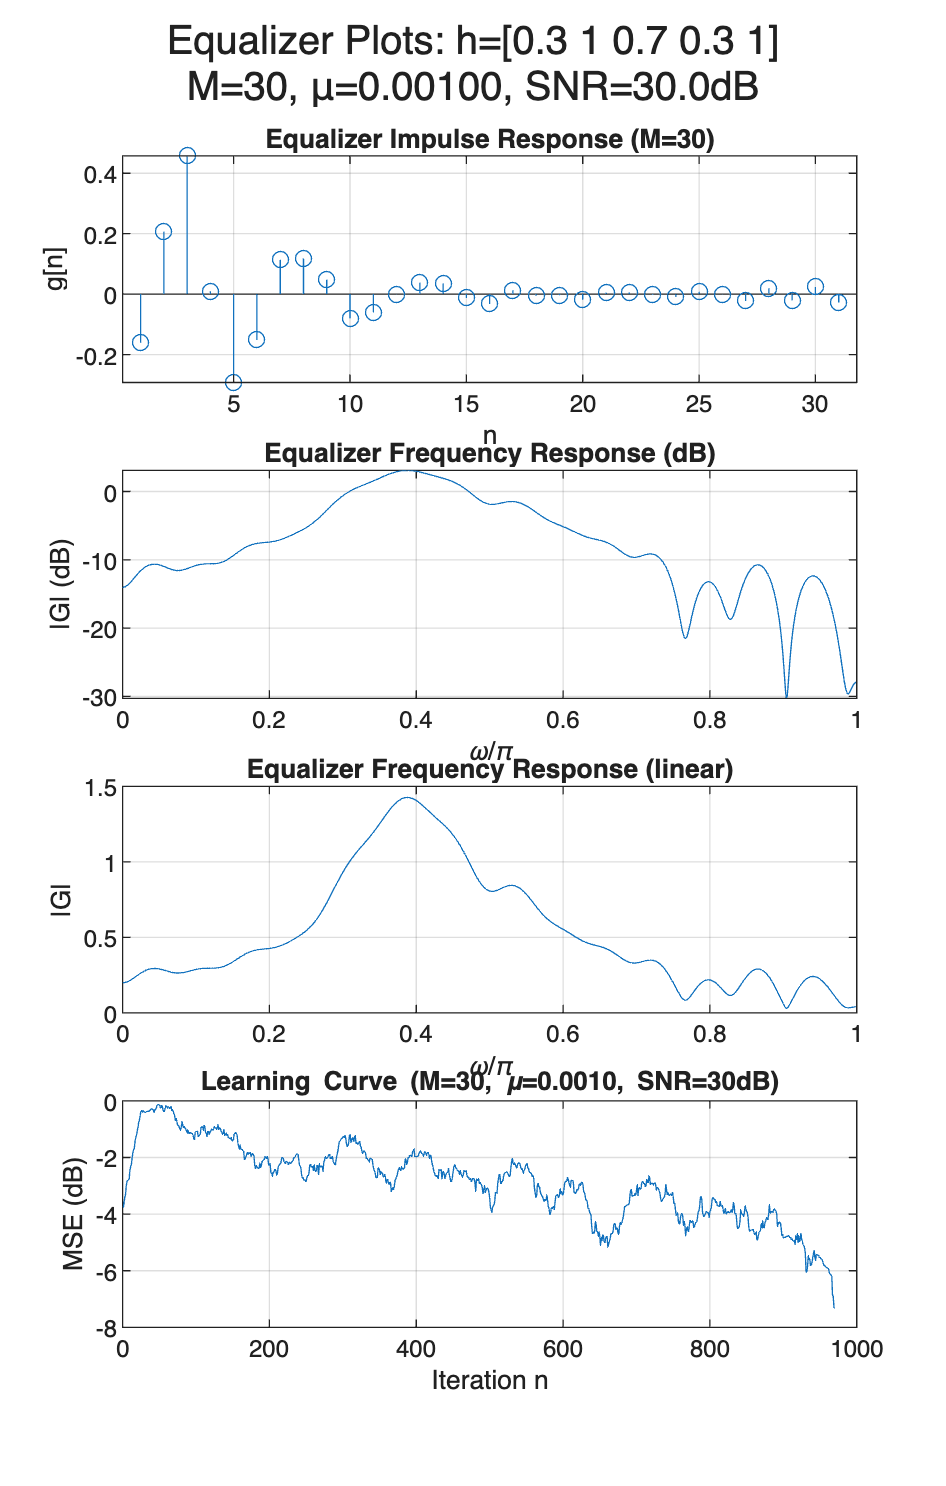

figure; plot_equalizer(h, gn, en, snr_db, mu, M, window);

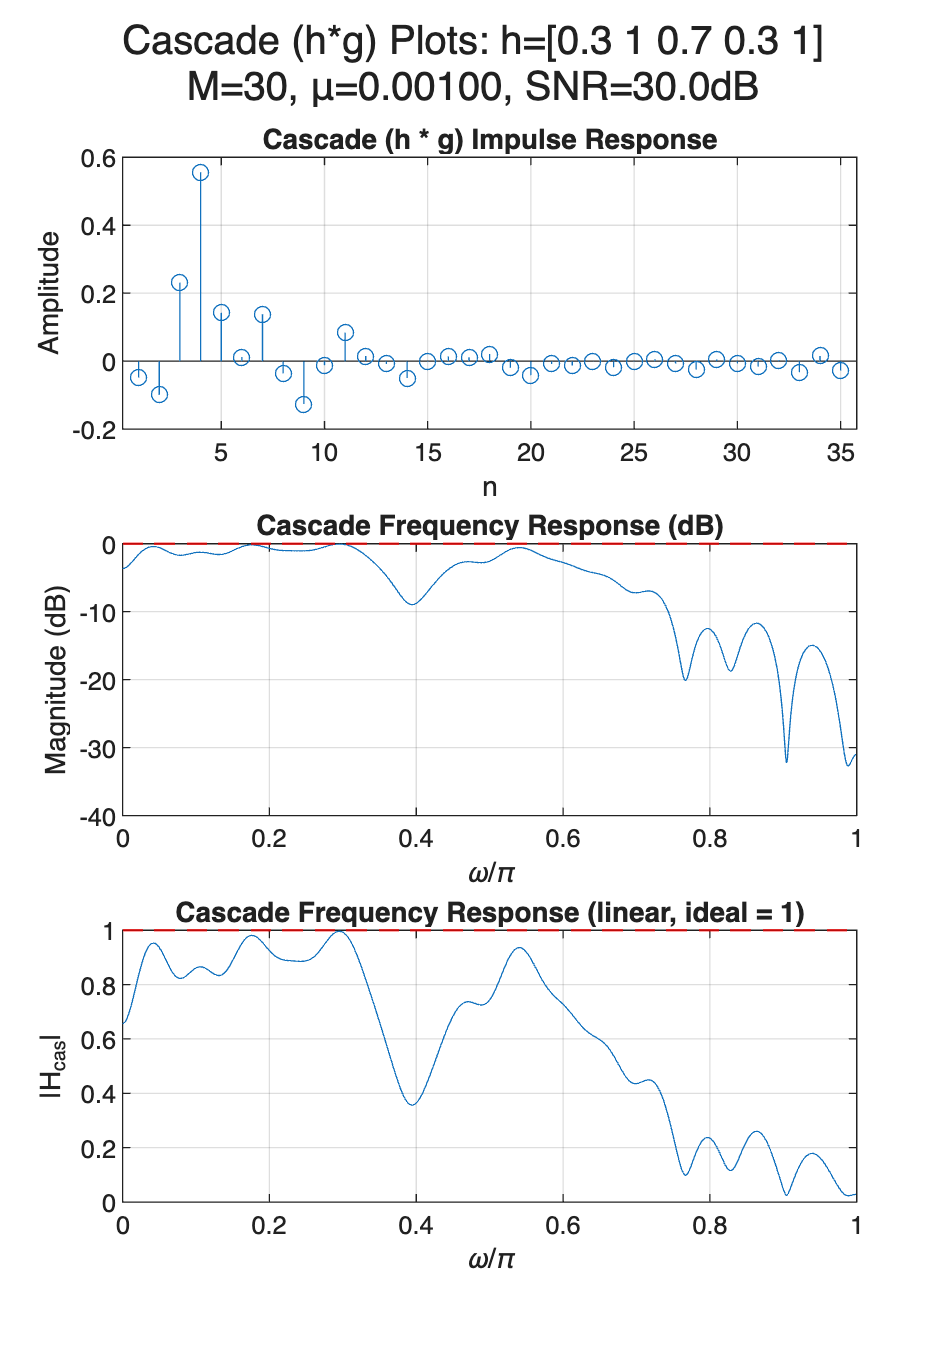

figure; plot_cascade(h, gn, snr_db, mu, M);


[BER_uneq, BER_eq] = compute_bit_error(h, gn, M, delay_idx, noi_power, V);
fprintf('Test 4 (SNR=%ddB, M=%d, mu=%.4f)\n', snr_db, M, mu);

Test 4 (SNR=30dB, M=30, mu=0.0010)


fprintf('Unequalized BER: %.4f\n', BER_uneq);

Unequalized BER: 0.4970


fprintf('Equalized   BER: %.4f\n', BER_eq);

Equalized   BER: 0.0757


% FOR LOOP TESTS
h_tests   = {[0.3,1,0.7,0.3,0.2], [1,0.5,0.2], [0.5,1,0.8,0.4,0.1,0.3]};
snr_tests = [20, 25, 30, 35];
M_tests   = [10, 20, 30];
mu_tests  = [0.01, 0.001, 0.0001];

results = [];

for h_idx = 1:length(h_tests)
    h_cur = h_tests{h_idx};
    for snr_db = snr_tests
        for M = M_tests
            for mu = mu_tests

                [g_cur, e_cur, yn_cur, xn_cur, noi_power_cur] = run_equalizer(train, h_cur, mu, M, delay_idx, snr_db, N);

                final_mse = mean(e_cur(end-100:end).^2);

                [BER_uneq, BER_eq] = compute_bit_error(h_cur, g_cur, M, delay_idx, noi_power_cur, V);
                
                % column indices: 1=h, 2=snr, 3=M, 4=mu, 5=MSE, 6=BER_uneq, 7=BER_eq
                results = [results; h_idx, snr_db, M, mu, final_mse, BER_uneq, BER_eq, delay_idx];
            end
        end
    end
end

## finding the best configuration

% best by equalized BER
[~, best_idx] = min(results(:,7));
best = results(best_idx, :);
fprintf('\n BEST CONFIGURATION (lowest equalized BER) \n');


 BEST CONFIGURATION (lowest equalized BER) 


fprintf('h = %d, SNR = %ddB, M = %d, mu = %.4f\n', best(1), best(2), best(3), best(4));

h = 1, SNR = 25dB, M = 10, mu = 0.0100


fprintf('Final MSE:       %.6f\n', best(5));

Final MSE:       0.063447


fprintf('Unequalized BER: %.4f\n', best(6));

Unequalized BER: 0.3862


fprintf('Equalized BER:   %.4f\n', best(7));

Equalized BER:   0.0000


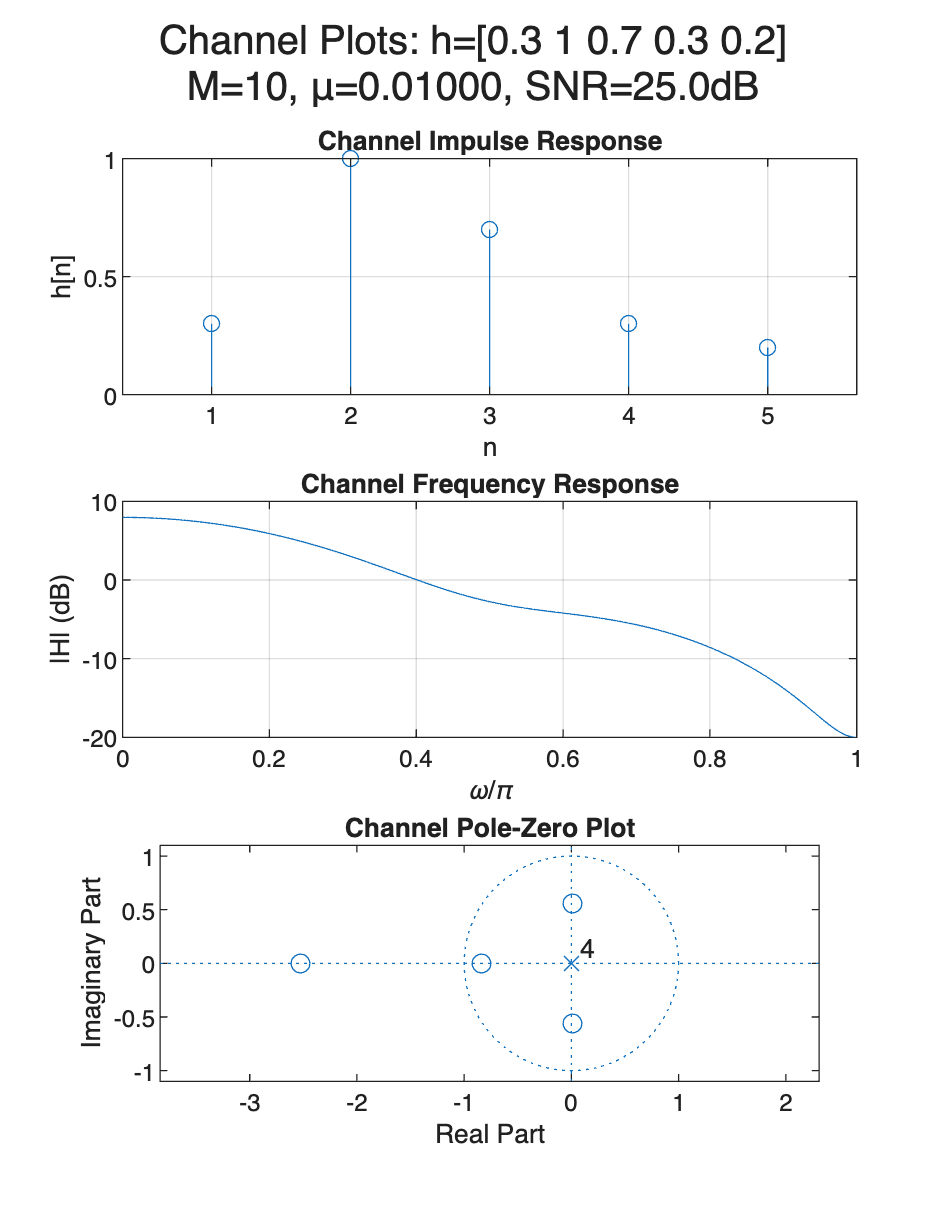


% plot best BER configuration
[gn_best, en_best, ~, ~, noi_best] = run_equalizer(train, h_tests{best(1)}, best(4), best(3), results(idx,8), best(2), N);
plot_channel(h_tests{best(1)}, best(2), best(4), best(3));

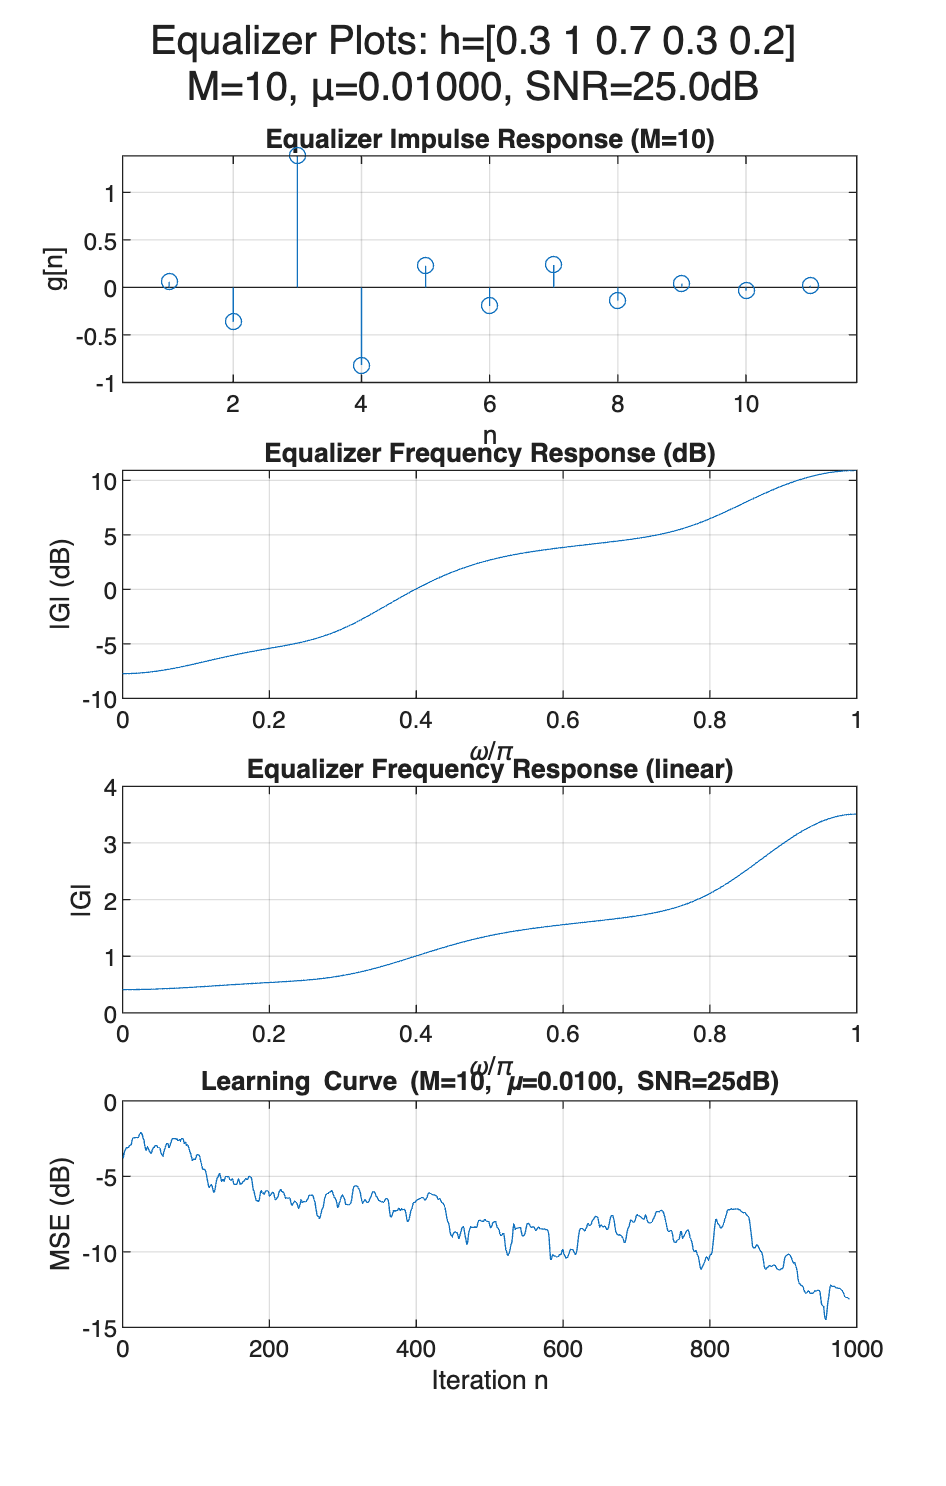

plot_equalizer(h_tests{best(1)}, gn_best, en_best, best(2), best(4), best(3), window);

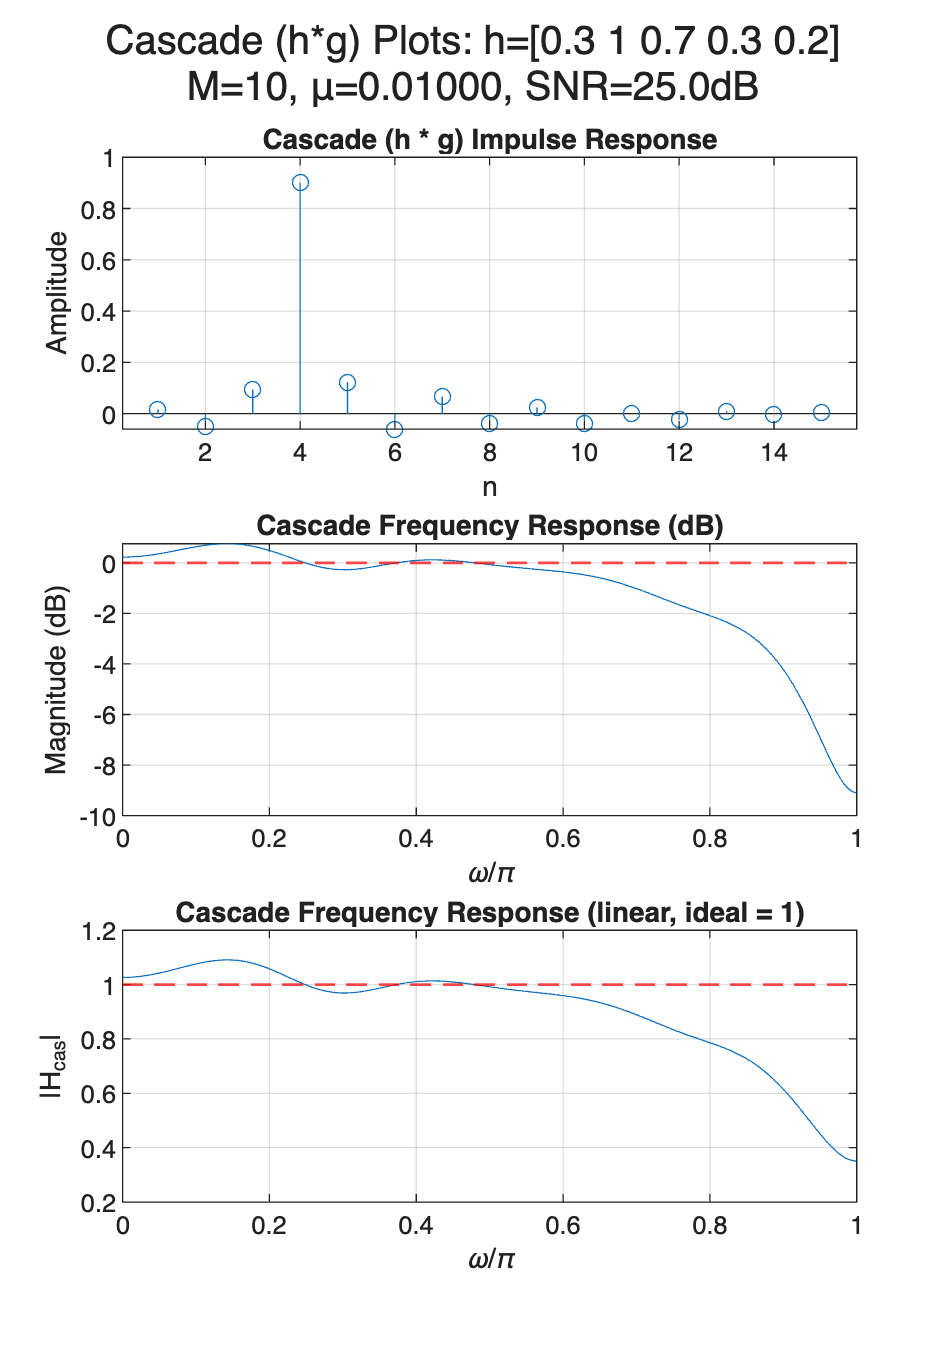

plot_cascade(h_tests{best(1)}, gn_best, best(2), best(4), best(3));


[BER_uneq_best, BER_eq_best] = compute_bit_error(h_tests{best(1)}, gn_best, best(3), results(idx,8), noi_best, V);
fprintf('\nBest BER config BER check:\n');


Best BER config BER check:


fprintf('Unequalized BER: %.4f\n', BER_uneq_best);

Unequalized BER: 0.3890


fprintf('Equalized   BER: %.4f\n', BER_eq_best);

Equalized   BER: 0.0000
